**Exercise 6 part (a)**

Plot SOD vs time

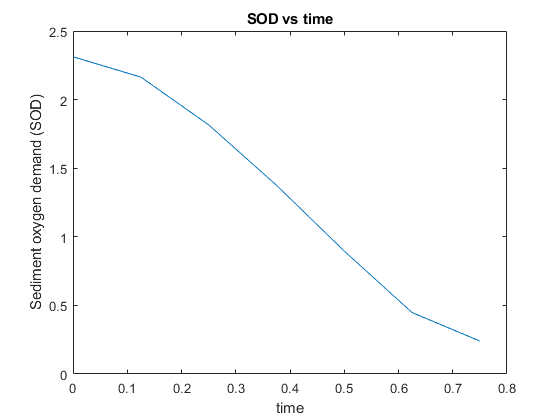

% Sediment oxygen demand (SOD) in g/(m^2*d)

t = [0 0.125 0.25 0.375 0.5 0.625 0.75]; % time d
O = (10^(-3)/0.001)*[10 7.11 4.59 2.57 1.15 0.33 0.03]; % oxygen g/L
n = length(t);
H = 0.1; % depth of water m
SOD = zeros(1,n);
dOdt = tabular_derivative(t,O);
    for i=1:n
        SOD(i) = -H*dOdt(i);
    end
plot(t,SOD)
xlabel('time');
ylabel('Sediment oxygen demand (SOD)');
title('SOD vs time')

**Exercise 5 part (b)**

Plot SOD vs oxygen concentration

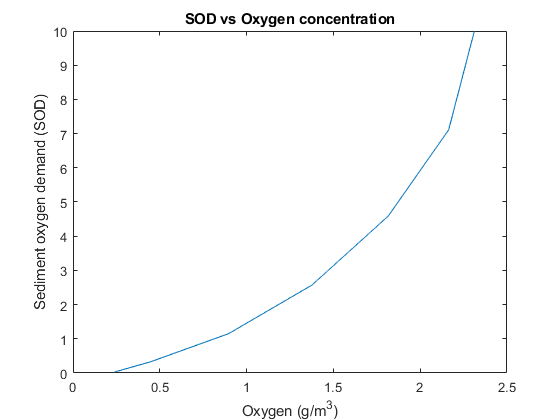

plot(SOD,O)
title('SOD vs Oxygen concentration');
xlabel('Oxygen (g/m^3)');
ylabel('Sediment oxygen demand (SOD)');

function [dydx] = tabular_derivative(x,y) % x is IV y=f(x)
n = length(x); dydx = zeros(1,n);
% forward difference for first point
dydx(1) = (y(2)-y(1))/(x(2)-x(1));
% central difference for interior points
for i=2:n-1
    dydx(i) = (y(i+1)-y(i-1))/(x(i+1)-x(i-1));
end
% backward difference for last point
dydx(n) = (y(n)-y(n-1))/(x(n)-x(n-1));
end